% Loading data from the student file
data = load("student.mat");
t = data.t;
input = data.r;
output = data.cn;
[~, Size] = size(t);


# Q1: SYSTEM IDENTIFICATION

% Parameters for the settling time metric
p5Criterion = 1.05*1;
p5CriterionLow = 0.95*1;
p5CriterionHigh = 1.05*1;

% To capture the local maxima and minima points
minima = islocalmin(output);
maxima = islocalmax(output);

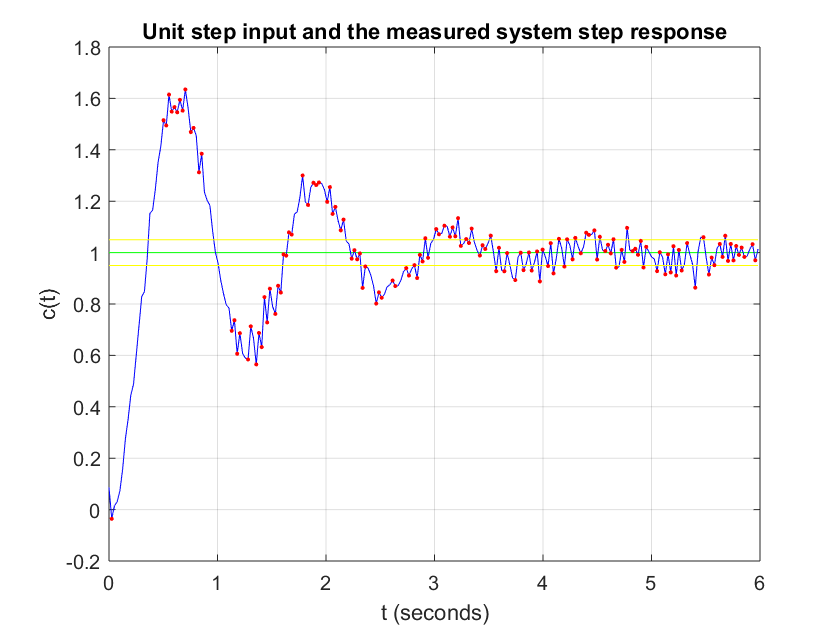

% The plot of the input-output data with noise
figure(1)
plot(t,input,'g',t,output,'b',t,p5CriterionLow*ones(Size), 'y',t,p5CriterionHigh*ones(Size), 'y', t(minima),output(minima),'r.', t(maxima), output(maxima),'r.');
title('Unit step input and the measured system step response');
grid on
ylabel("c(t)")
xlabel("t (seconds)")

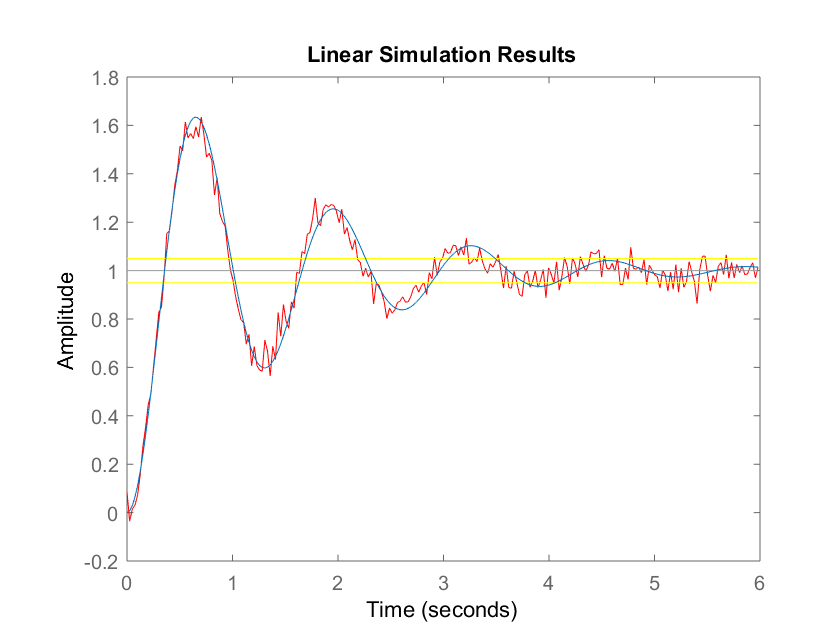

S = stepinfo(output);
setValue = 1;
% the max Overshoot and Percent Overshoot
peak = ( max(output) - setValue )/ setValue;

% An estimate of the zeta value
zeta = (-log(peak))/sqrt( ((pi).^2) + (log(peak)).^2 );

% An estimate of the natural frequency using a Ts = 4.3 secs from the graph above
% Using 5% criterion
Ts = 4.3;
Wn = 3/(Ts * zeta);

% An estimate of the system transfer function
H = tf([ Wn.^2],[1 2*zeta*Wn Wn.^2]);
u = heaviside(0);
figure(2)
plot(t,output,'r',t,p5CriterionLow*ones(Size), 'y',t,p5CriterionHigh*ones(Size),'y');
grid on
hold on
lsim(H, input, t)